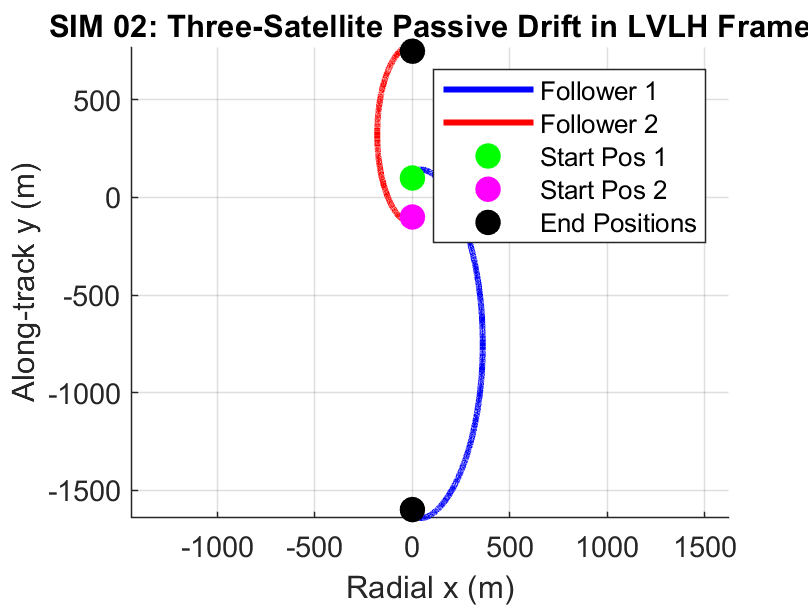

%% ========================================================================
%  SIM_02_ThreeSat_PassiveDrift
%  --------------------------------------------------------------
%  - Simulates passive relative motion of two follower satellites 
%    with respect to a leader satellite using the Clohessy-Wiltshire (CW)
%    equations in the Local-Vertical Local-Horizontal (LVLH) frame.
%
%  - No control inputs applied (followers drift naturally).
%  - Motion is integrated over 3 orbits.
%
%  Author: Sabrina Nicacio
% ========================================================================

clc; clear; close all;

%% === PARAMETERS ===
% Define orbital and system parameters
mu = 3.986e14;            % Earth's gravitational parameter (m^3/s^2)
Re = 6371e3;              % Earth radius (m)
alt = 500e3;              % Orbital altitude (m)
a = Re + alt;             % Semi-major axis (m)
n = sqrt(mu / a^3);       % Mean motion (rad/s)

T = 2*pi / n;             % Orbital period (s)
N_orbits = 1;             % Number of orbits to simulate

% Time settings
dt = .5;                   % Time step (s)
% originally tried with dt = 1
tspan = 0:dt:(N_orbits * T); % Total simulation time

%% === INITIAL RELATIVE STATES FOR FOLLOWERS ===
% State vector: [x; y; z; x_dot; y_dot; z_dot]
% x  = Radial distance (m)
% y  = Along-track distance (m)
% z  = Cross-track distance (m)
% x_dot, y_dot, z_dot = Velocities in respective directions (m/s)

% Follower 1: Starts 100m ahead in y-direction
x0_follower1 = [0; 100; 0; 0; 0.1; 0];  

% Follower 2: Starts 100m behind in y-direction and offset in z
% x0_follower2 = [0; -100; 50; 0; -0.1; 0];  
x0_follower2 = [0; -100; 50; 0; -0.05; 0];  % Reduce y_dot from -0.1 to -0.05 m/s


%% === CLOHESSY-WILTSHIRE EQUATIONS IN MATRIX FORM ===
A = [  0     0     0     1     0     0;
       0     0     0     0     1     0;
       0     0     0     0     0     1;
     3*n^2   0     0     0   2*n     0;
       0     0     0  -2*n     0     0;
       0     0  -n^2    0     0     0];

% Define function handle for numerical integration
cw_dynamics = @(t, x) A * x;

%% === SOLVE USING ODE45 FOR BOTH FOLLOWERS ===
[t, x_follower1] = ode45(cw_dynamics, tspan, x0_follower1);
[t, x_follower2] = ode45(cw_dynamics, tspan, x0_follower2);

% Transpose solutions for easier plotting
x_follower1 = x_follower1';
x_follower2 = x_follower2';

%% === PLOT RELATIVE MOTION IN LVLH FRAME ===
figure;
hold on;
plot(x_follower1(1,:), x_follower1(2,:), 'b', 'LineWidth', 2); % Follower 1
plot(x_follower2(1,:), x_follower2(2,:), 'r', 'LineWidth', 2); % Follower 2
plot(x_follower1(1,1), x_follower1(2,1), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');  % Start Pos 1
plot(x_follower2(1,1), x_follower2(2,1), 'mo', 'MarkerSize', 8, 'MarkerFaceColor', 'm');  % Start Pos 2
plot(x_follower1(1,end), x_follower1(2,end), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); % End Pos 1
plot(x_follower2(1,end), x_follower2(2,end), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); % End Pos 2
xlabel('Radial x (m)');
ylabel('Along-track y (m)');
title('SIM 02: Three-Satellite Passive Drift in LVLH Frame');
legend('Follower 1', 'Follower 2', 'Start Pos 1', 'Start Pos 2', 'End Positions');
grid on;
axis equal;
hold off;

%% === SAVE FIGURE FOR DOCUMENTATION ===
saveas(gcf, 'SIM_02_ThreeSat_PassiveDrift.png');  % Save plot as an image


%% === END OF SIMULATION ===
disp('Simulation completed: SIM_02_ThreeSat_PassiveDrift');

Simulation completed: SIM_02_ThreeSat_PassiveDrift
